%% AUTHOR INFORMATION
% NAME: Balaji V
% EMAIL: ee19d202@smail.iitm.ac.in
% Code to analyse the output from ./Test_Write_Drivers

## Preface

    clear ;
    clc ;
    if( ~exist( 'globalVars', 'var' ) )
        globalVars=[];
    end
    eval( [ 'clearvars -except globalVars ' sprintf( '%s ', globalVars ) ] ) ;
    close all ;
    zeroes = @( x ) zeros( x ) ;
    addpath("D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\lowerLevelCode\FPGA_COMMUNICATE");
    addpath("D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\lowerLevelCode\FPGA_CONTROL");
    addpath("D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\lowerLevelCode\MISC");
    addpath("D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\lowerLevelCode\POWER_SUPPLY_CONTROL");


## Go to Global

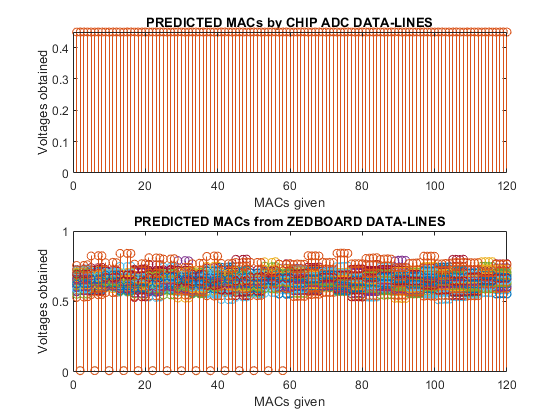

% Global : D:\Xilinx\Vivado_2018_Projs\Srinidhi_Laptop\PCB_TEST_FPGA_ARM\Character_Files\new_C_code_UART_files\10_vecfile_auto_FA\7_vecfile_auto_FA
% cd( '../../../' ) ;
%     fileName = mfilename ; 
    filePath = matlab.desktop.editor.getActiveFilename ;
    b = find( filePath == '\', 1, 'last' ) ; 
    fileName = filePath( ( b + 1 )  : ( end - 4 ) ) ;
    b = find( fileName == '_', 1, 'last' ) ; 
    sourceFileName = fileName( 1 : ( b - 1 ) ) ;
driverCode_fileName         = sprintf( '/%s', sourceFileName ) ;
filePath            = '.' ;
fpgaReceivedFile_name       = [ filePath '/fpgaRcvdFiles' driverCode_fileName ] ;
[    fpgaReceivedFile_decrypted ...
            , adc_VPVN ...
            , adc_AUX00 ...
            ,    SA_SC_collect    ...
            ,    ADC_SC_collect  ...
            ,    AdderTree_SC_collect  ...
            ,    SARTIMING_OUT_SC_collect  ...
            ,    WRITE_2_SC_collect  ...
            ,    WRITE_1_SC_collect  ...
            ,    WRITE_0_SC_collect  ...
            ,    IMC_RBL_SC_collect  ...
            ,    IMC_VOut_SC_collect  ...
            ,    WWL_SC_collect  ...
            ,    FLOATADC_SC_collect  ...
            ,    SARTIMING_IN_SC_collect  ...
            ,    ControlPath_SC_collect  ...
            ,    Reset_DFF_collect  ...
            ,    SAR_Bin_Num ...
            ,     read_SRAM_collect_Cell ...
            ,    perform_hybridIMC_BLIMG_FPGA_collect...
            ,    perform_internalIMC_ImgBankFPGA_collect  ] = decrypt_and_RSC( fpgaReceivedFile_name ) ;
%% cd'ing back
    cd( filePath ) ;
%% saving data
    c = clock ;
    year    = c(1) ;
    month   = c(2) ; 
    day     = c(3) ;
    hour    = c(4) ;
    minute  = c(5) ;
    seconds = floor(c(6)) ;
save( [ sprintf( './analyzeResults/%s_%s_%d_%d_%d', fileName, date,hour,minute,seconds) ] ) ;

ADC_predicted=[];
for iter=1:size(perform_hybridIMC_BLIMG_FPGA_collect,1)
    a=reshape(perform_hybridIMC_BLIMG_FPGA_collect(iter,:),[],92);b=2.^[0,1,2,3,4,5,6]';c=b'*a;ADC_predicted=[ADC_predicted;c];
end
ADC_predicted_volts=(ADC_predicted/(2^7))*0.9;

ZEDBOARD_ADC=reshape(adc_VPVN,88,[]);ZEDBOARD_ADC=ZEDBOARD_ADC';
ZEDBOARD_ADC_Ref=reshape(adc_AUX00,88,[]);ZEDBOARD_ADC_Ref=ZEDBOARD_ADC_Ref';

%numOnesRefArray=[142:-4:105];
%numOnesData_DL_array=147;
%xdata=(numOnesData_DL_array-numOnesRefArray)*4;
%xdata=xdata';
%xdata=repmat(xdata,1,92);

DL_indices=[1:18,27:62,71:88];
RL_indices=[19:26,63:70];
figure(1);
subplot(2,1,1)
stem(ADC_predicted_volts(:,DL_indices+2));
title('PREDICTED MACs by CHIP ADC DATA-LINES');
xlabel('MACs given');
ylabel('Voltages obtained');
hold on;

subplot(2,1,2)
stem(ZEDBOARD_ADC(:,DL_indices));
title('PREDICTED MACs from ZEDBOARD DATA-LINES');
xlabel('MACs given');
ylabel('Voltages obtained');
hold on;

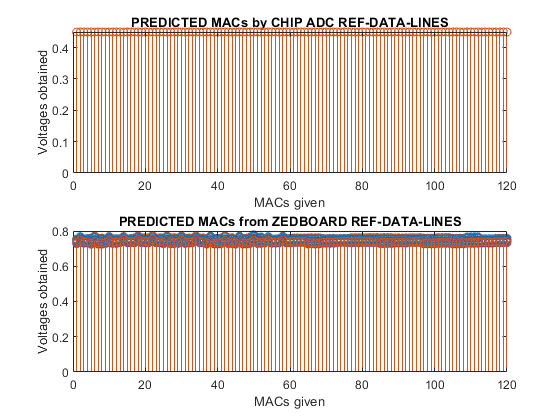


figure(2);
subplot(2,1,1)
stem(ADC_predicted_volts(:,RL_indices+2));
title('PREDICTED MACs by CHIP ADC REF-DATA-LINES');
xlabel('MACs given');
ylabel('Voltages obtained');
hold on;
subplot(2,1,2)
stem(ZEDBOARD_ADC_Ref(:,RL_indices));
title('PREDICTED MACs from ZEDBOARD REF-DATA-LINES');
xlabel('MACs given');
ylabel('Voltages obtained');
hold on;

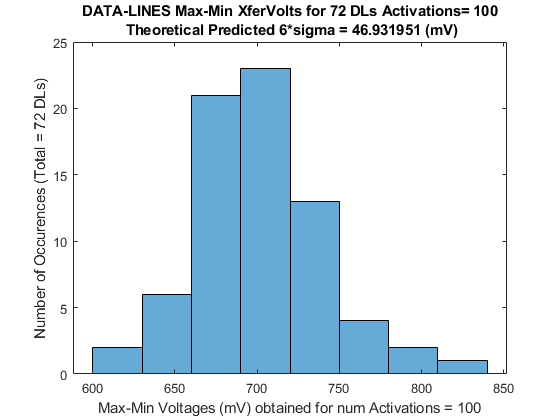



figure(3);
DL_Xfers=ZEDBOARD_ADC(:,DL_indices);
ZEDBOARD_ADC_max=max(DL_Xfers,[],1);ZEDBOARD_ADC_min=min(DL_Xfers,[],1);
ZEDBOARD_ADC_maxMmin=ZEDBOARD_ADC_max-ZEDBOARD_ADC_min;
histogram(ZEDBOARD_ADC_maxMmin*1E3);
numActivations=100;
load('D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\Control_Codes\Testing\017_ReadStackAlphaMeasurement\IMC_RBL_ReadStacks.mat');
sigma_Ireadstacks=std(IMC_RBL_ReadStacks);
Res=9E3;
theoreticalPredicted=sqrt(numActivations)*6*sigma_Ireadstacks*Res;
title(sprintf('DATA-LINES Max-Min XferVolts for 72 DLs Activations= %d\n Theoretical Predicted 6*sigma = %f (mV)',numActivations,theoreticalPredicted*1E3));
ylabel('Number of Occurences (Total = 72 DLs)');
xlabel(sprintf('Max-Min Voltages (mV) obtained for num Activations = %d',numActivations));

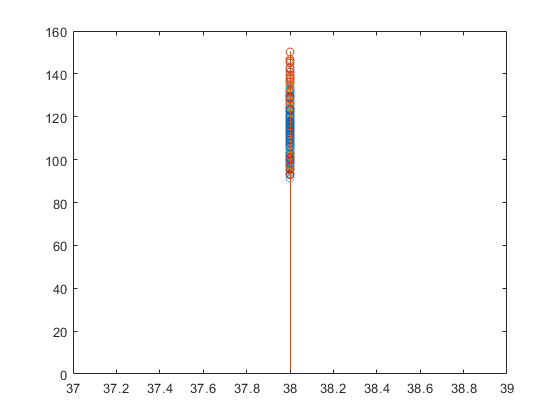


%8-Bit Weights
load('D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\Control_Codes\Testing\026_DotProductCompute\SDCard_BinFiles\dataCols_4XRandomize.mat');

figure();
dataDL=adc_VPVN;
dataDLMAcs=(reshape(dataDL,88,4,[])/0.9)*160;%MACs
MSB_powers=2.^[1 0 -1 -2];MSB_powers(1)=-MSB_powers(1);
LSB_powers=2.^[-3 -4 -5 -6];
powerCombs=cat(3,repmat(MSB_powers,72,1,size(dataCols,1)),repmat(LSB_powers,72,1,size(dataCols,1)));
arrDL=[[1:18],8+[19:54],16+[55:72]];dataDLMAcs=dataDLMAcs(arrDL,:,:);
dataDLMAcs=dataDLMAcs.*powerCombs;
dataDLMAcs=sum(dataDLMAcs,2);
dataDLMAcs=reshape(dataDLMAcs,72,size(dataCols,1),2);
dataDLMAcs=sum(dataDLMAcs,3);
dataDLMAcs=dataDLMAcs';
x_array = sum(dataCols,2);
stem(x_array ,-dataDLMAcs);


%4-Bit Weights
% figure();
% dataDL=adc_VPVN;
% dataDLMAcs=(reshape(dataDL,88,4,[])/0.9)*160;%MACs
% MSB_powers=2.^[0 -1 -2 -3];
% powerCombs=repmat(MSB_powers,72,1,15);
% arrDL=[[1:18],8+[19:54],16+[55:72]];dataDLMAcs=dataDLMAcs(arrDL,:,:);
% dataDLMAcs=dataDLMAcs.*powerCombs;
% dataDLMAcs=sum(dataDLMAcs,2);
% dataDLMAcs=reshape(dataDLMAcs,72,15,1);
% dataDLMAcs=sum(dataDLMAcs,3);
% dataDLMAcs=dataDLMAcs';
% x_array = [10:10:150];
% stem(x_array ,dataDLMAcs);


save('./SDCard_BinFiles/dataAlphaUNCorrected/alphaUNCorrected_4X_MAC155_SUB_120.mat','adc_AUX00','adc_VPVN');